# EQUACIONS NO LINEALS

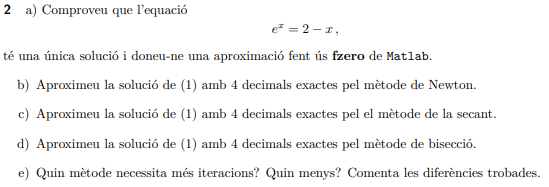

- `Comproveu que l'equació té una solució`

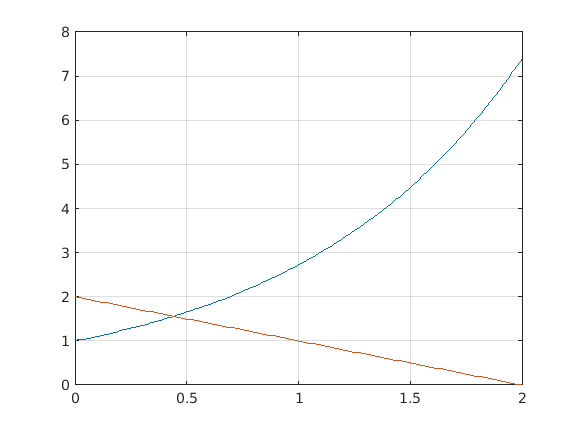

t = linspace(0,2);
plot(t,exp(t),t,2-t),grid

t = (0:0.1:1)';
f = @(x)exp(x)-2+x;
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t       f(t)  
    ___    ________

      0          -1
    0.1    -0.79483
    0.2     -0.5786
    0.3    -0.35014
    0.4    -0.10818
    0.5     0.14872
    0.6     0.42212
    0.7     0.71375
    0.8      1.0255
    0.9      1.3596
      1      1.7183



- `Aproximeu la solució amb tres decimals exactes pel mètode de Newton`

f = @(x) exp(x)+x-2;
fp = @(x) exp(x)+1;
a = 0.4; b = 0.5; n = 50; tol = 0.0005;
newton(f,fp,a,tol,n)

    k          x                   f                   l
    0   0.400000000000000  -0.108175302358730                    
    1   0.443412083707625   0.001426318064278   0.043412083707625
    2   0.442854495698488   0.000000242151722   0.000557588009136
    3   0.442854401002391   0.000000000000007   0.000000094696097


ans = 0.4429

- `Aproximeu la solució amb tres decimals exactes pel mètode de la secant`

secant(f,a,b,tol,tol,n)

    k          x                   f                   l
        0.400000000000000  -1.081753023587297e-01                    
        0.500000000000000   1.487212707001282e-01                    
    1   0.442108503461409  -1.906935552690836e-03   0.057891496538591
    2   0.442841403066962  -3.323748183503561e-05   0.000732899605553
    3   0.442854403954195   7.548197622497810e-09   0.000013000887232


ans = 0.4429

- `Aproximeu la solució amb tres decimals exactes pel mètode de la bisecció`

bisect(f,a,b,n,tol)

    k          x                   f                   l
        0.400000000000000  -0.108175302358730                    
        0.500000000000000   0.148721270700128                    
    1   0.450000000000000   0.018312185490169   0.050000000000000
    2   0.425000000000000  -0.045409580336621   0.025000000000000
    3   0.437500000000000  -0.013669701365867   0.012500000000000
    4   0.443750000000000   0.002290801713028   0.006250000000000
    5   0.440625000000000  -0.005697036150776   0.003125000000000
    6   0.442187500000000  -0.001705016764528   0.001562500000000
    7   0.442968750000000   0.000292417216759   0.000781250000000
    8   0.442578125000000  -0.000706418541850   0.000390625000000
        0.442773437500000  -0.000207030360337   0.000195312500000


ans = 0.4428

- `Calculeu el valor aproximat fent ús de ``zeroin/fzero`` de MATLAB®`

zeroin(f,a,b)

    1  initial   0.400000000000000  -1.081753023587297e-01
    2  initial   0.500000000000000   1.487212707001282e-01
    3  secant    0.442108503461409  -1.906935552690836e-03
    4  secant    0.442864120628912   2.485457374090672e-05
    5  secant    0.442854398795079  -5.644412492955553e-09
    6  secant    0.442854401002382  -1.665334536937735e-14
    7  secant    0.442854401002389  -2.220446049250313e-16
    8  minimal   0.442854401002389   0.000000000000000e+00
    9  minimal   0.442854401002389   0.000000000000000e+00
   10  minimal   0.442854401002389   4.440892098500626e-16


ans = 0.4429

options = optimset('Display','iter'); % show iterations
[x fval exitflag output] = fzero(f,[a,b],options)

 
 Func-count    x          f(x)             Procedure
    2             0.4     -0.108175        initial
    3        0.442109   -0.00190694        interpolation
    4        0.442855   3.92781e-07        interpolation
    5        0.442854  -8.91998e-11        interpolation
    6        0.442854             0        interpolation
 
Zero found in the interval [0.4, 0.5]


x = 0.4429

fval = 0

exitflag = 1

output = struct with fields:
    intervaliterations: 0
            iterations: 4
             funcCount: 6
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.4, 0.5]'


[x fval exitflag output] = fzero(f,1,options)

 
Search for an interval around 1 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1               1       1.71828             1       1.71828   initial interval
    3        0.971716       1.61419       1.02828       1.82455   search
    5            0.96        1.5717          1.04       1.86922   search
    7        0.943431       1.51221       1.05657       1.93305   search
    9            0.92       1.42929          1.08       2.02468   search
   11        0.886863       1.31437       1.11314       2.15703   search
   13            0.84       1.15637          1.16       2.34993   search
   15        0.773726      0.941554       1.22627       2.63478   search
   17            0.68      0.653878          1.32       3.06342   search
   19        0.547452      0.276293       1.45255       3.72654   search
   20            0.36     -0.206671       1.45255       3.72654   search
 
Search for a zero in the interval [0.36, 1.45255]

x = 0.4429

fval = 0

exitflag = 1

output = struct with fields:
    intervaliterations: 10
            iterations: 5
             funcCount: 25
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.36, 1.45255]'


- Comproveu que l'equació té solució

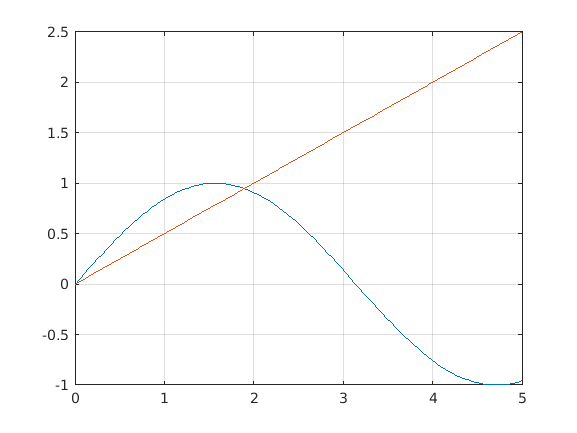

t = linspace(0,5);
plot(t,sin(t),t,t/2), grid

t = (1:0.1:2)';
f = @(x)sin(x)-x/2;
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t        f(t)   
    ___    __________

      1       0.34147
    1.1       0.34121
    1.2       0.33204
    1.3       0.31356
    1.4       0.28545
    1.5       0.24749
    1.6       0.19957
    1.7       0.14166
    1.8      0.073848
    1.9    -0.0036999
      2     -0.090703



a = 1.8; b = 1.9; n = 50; tol = 0.0005;
fp = @(x) cos(x) - 1/2;
newton(f,fp,a,tol,n)

    k          x                   f                   l
    0   1.800000000000000   0.073847630878195                    
    1   1.901550355007382  -0.004977440477837   0.101550355007382
    2   1.895515310951794  -0.000017235652538   0.006035044055588
    3   1.895494267290198  -0.000000000209847   0.000021043661597


ans = 1.8955

secant(f,a,b,tol,tol,n)

    k          x                   f                   l
        1.800000000000000   7.384763087819513e-02                    
        1.900000000000000  -3.699912312585485e-03                    
    1   1.895228846510994   2.173520022317188e-04   0.004771153489006
    2   1.895493577119002   5.650556821334973e-07   0.000264730608008


ans = 1.8955

bisect(f,a,b,n,tol)

    k          x                   f                   l
        1.800000000000000   0.073847630878195                    
        1.900000000000000  -0.003699912312585                    
    1   1.850000000000000   0.036275202975300   0.050000000000000
    2   1.875000000000000   0.016585781609694   0.025000000000000
    3   1.887500000000000   0.006517173304812   0.012500000000000
    4   1.893750000000000   0.001427151962228   0.006250000000000
    5   1.896875000000000  -0.001131754662609   0.003125000000000
    6   1.895312500000000   0.000148855638229   0.001562500000000
    7   1.896093750000000  -0.000491160341149   0.000781250000000
    8   1.895703125000000  -0.000171080049178   0.000390625000000
        1.895507812500000  -0.000011094128715   0.000195312500000


ans = 1.8955

syms t
f = @(x) x.^3+2.*x-2;
x0 = bisect(f,-2,2,10,0.25);

    k          x                   f                   l
       -2.000000000000000 -14.000000000000000                    
        2.000000000000000  10.000000000000000                    
    1   0.000000000000000  -2.000000000000000   2.000000000000000
    2   1.000000000000000   1.000000000000000   1.000000000000000
    3   0.500000000000000  -0.875000000000000   0.500000000000000
    4   0.750000000000000  -0.078125000000000   0.250000000000000
        0.875000000000000   0.419921875000000   0.125000000000000


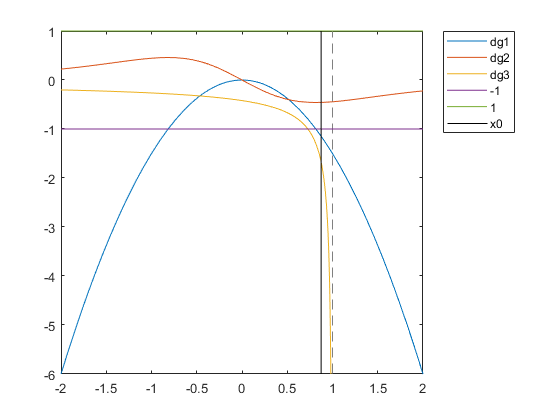

g1(t) = 1-0.5*t^3;
dg1(t) = diff(g1(t),t);
g2(t) = 2*(t^2+2)^(-1);
dg2(t) = diff(g2(t),t);
g3(t) = (2-2*t)^(1/3);
dg3(t) = diff(g3(t),t);
fplot([dg1,dg2,dg3,-1,1],[-2,2])
hold on
line([x0,x0],[-6,1],'Color','k'), hold off
legend('dg1','dg2','dg3','-1','1','x0','Location','bestoutside')

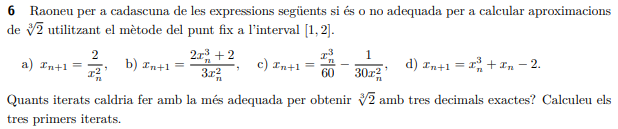

% Prac7_07abril_exer1.mlx

% Prac7_07abril_exer3.mlx
